https://www.mathworks.com/help/symbolic/solve-differential-equation-numerically-1.html

syms y(t)
[V] = odeToVectorField(diff(y, 2) == (1 - y^2)*diff(y) - y)

$$V = \left(\begin{array}{c} Y_{2}\\ -\left({Y_{1}}^{2}-1\right)\,Y_{2}-Y_{1} \end{array}\right)$$

M = matlabFunction(V,'vars', {'t','Y'})

M = function_handle with value:
    @(t,Y)[Y(2);-(Y(1).^2-1.0).*Y(2)-Y(1)]


sol = ode45(M,[0 20],[2 0]);
fplot(@(x)deval(sol,x,1), [0, 20])

applying classic spring damper model

syms y(t)
%constants
k = 1; %spring
c = 1; %damper
m = 1; %mass
[V] = odeToVectorField(-m*diff(y, 2) == c*diff(y) + k*y)

$$V = \left(\begin{array}{c} Y_{2}\\ -Y_{1}-Y_{2} \end{array}\right)$$

M = matlabFunction(V,'vars', {'t','Y'})

M = function_handle with value:
    @(t,Y)[Y(2);-Y(1)-Y(2)]


sol = ode45(M,[0 20],[0 2]);
fplot(@(x)deval(sol,x,1), [0, 20])

confirm by solving mathematically by hand

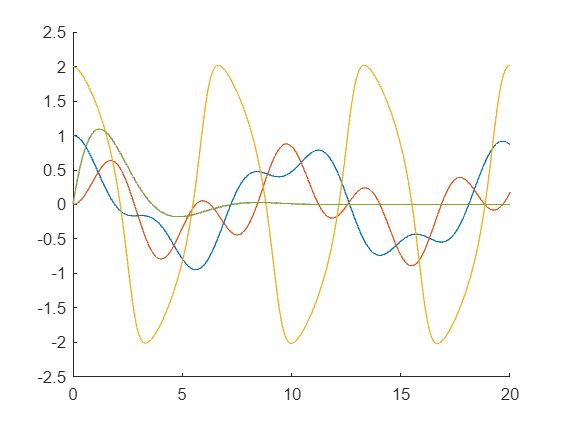

x = linspace(0,20,10000);
y = (4/sqrt(3))*exp(-1/2.*x).*sin(x.*sqrt(3)/2);
plot(x,y)

2 DOF spring sys (https://www.mathworks.com/help/symbolic/solve-a-system-of-differential-equations.html#SolveASystemOfDifferentialEquationsExample-2)

m = 1;
k = 2; %why are these not used????
syms x(t) y(t)
A = [-4 2; 2 -2];
Y = [x; y];
odes = diff(Y,2) == A*Y

$$odes(t) = \left(\begin{array}{c} \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=2\,y\left(t\right)-4\,x\left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=2\,x\left(t\right)-2\,y\left(t\right) \end{array}\right)$$

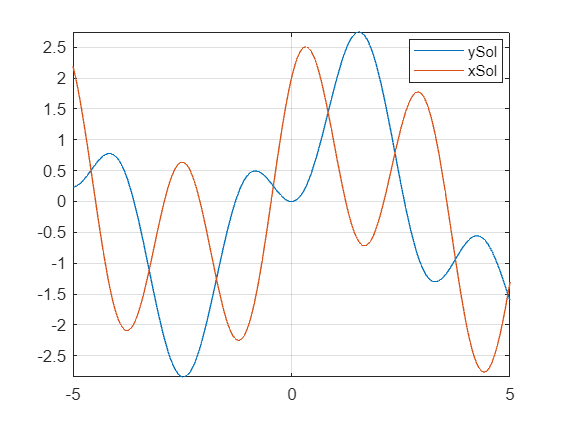

D = diff(Y);
C = [Y(0) == [2;0;],D(0) == [3;0]];
[xSol(t),ySol(t)] = dsolve(odes,C);
xSol(t) = simplify(xSol(t));
ySol(t) = simplify(ySol(t));
clf
fplot(ySol)
hold on
fplot(xSol)
grid on
legend('ySol','xSol','Location','best')

confirm by graphing system of first order ODEs 

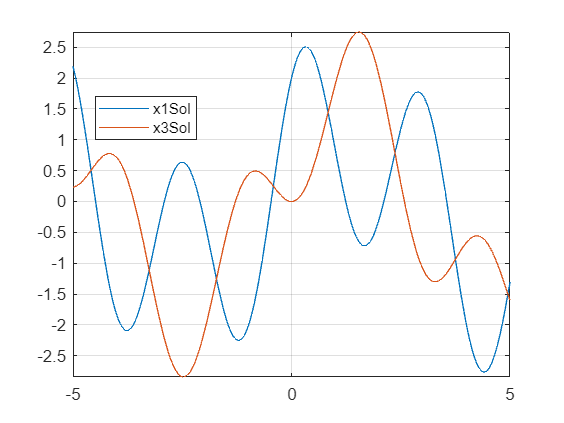

syms x1(t) x2(t) x3(t) x4(t)
A = [0 1 0 0; -4 0 2 0; 0 0 0 1; 2 0 -2 0];
Y = [x1; x2; x3; x4];
odes = diff(Y) == A*Y;
C = [Y(0) == [2;3;0;0;]];
[x1Sol(t),x2Sol(t),x3Sol(t),x4Sol(t)] = dsolve(odes,C);
x1Sol(t) = simplify(x1Sol(t));
x3Sol(t) = simplify(x3Sol(t));
clf
fplot(x1Sol)
hold on
fplot(x3Sol)
grid on
legend('x1Sol','x3Sol','Location','best')

2dof mass spring damper system (solved numerically) assum. identical mass and constants

clf
hold on
m = 1;
k = 1; 
c = 0;
syms x(t) y(t)
A = [-(2*k/m) k/m; k/m -k/m];
B = [-2*c/m c/m; c/m -c/m];
Y = [x; y];
[V] = odeToVectorField(diff(Y,2) == A*Y + B*diff(Y))

$$V = \left(\begin{array}{c} Y_{2}\\ Y_{3}-Y_{1}\\ Y_{4}\\ Y_{1}-2\,Y_{3} \end{array}\right)$$

M = matlabFunction(V,'vars', {'t','Y'})

M = function_handle with value:
    @(t,Y)[Y(2);-Y(1)+Y(3);Y(4);Y(1)-Y(3).*2.0]



timeSpan = [0 20]; % Interval
stepSize = 0.01; % Smaller step size for more time points
timeGrid = timeSpan(1):stepSize:timeSpan(2); % Create a finer time grid

%sol = ode45(M,[0 20],[1 0 0 0])
sol = ode45(M,timeGrid,[1 0 0 0])

sol = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 2.0095e-04 0.0012 0.0062 0.0313 0.1569 0.5362 1.0071 1.5127 2.0639 2.5656 2.9379 3.3102 3.7487 4.2494 4.7099 5.2160 5.6547 6.0935 6.4580 6.9198 7.4175 7.9202 8.4329 8.9166 9.3353 9.9016 10.3979 10.8847 11.4086 11.8683 12.3459 12.7991 … ]
          y: [4×49 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


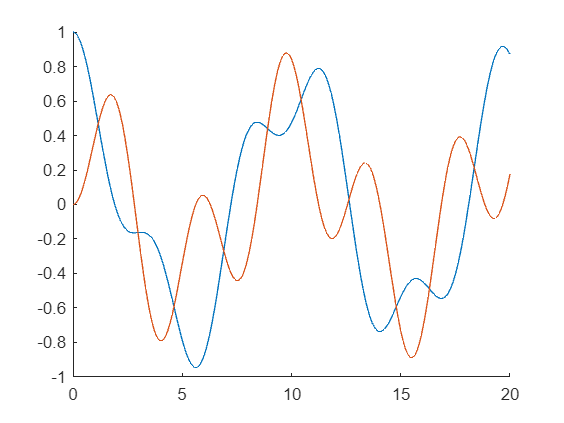


fplot(@(x)deval(sol,x,1), [0, 20])
fplot(@(x)deval(sol,x,3), [0, 20])


% Extract time points and solution values
timePoints = sol.x;
solutionValues = deval(sol, timePoints, 1:4) % Assuming the solution has 4 components

solutionValues =     1.0000    1.0000    1.0000    1.0000    0.9995    0.9877    0.8630    0.5716    0.2172   -0.0604   -0.1577   -0.1639   -0.1650   -0.2213   -0.4005   -0.6407   -0.8741   -0.9449   -0.8376   -0.6211   -0.2500    0.1411    0.3991    0.4769    0.4389    0.4025    0.4512    0.5953    0.7442    0.7763    0.6179    0.2789   -0.1200   -0.4446   -0.6753   -0.7345   -0.6449   -0.5103   -0.4300   -0.4567   -0.5168   -0.5439   -0.4449   -0.1648    0.2043    0.5932    0.8468    0.9165    0.8695
         0   -0.0002   -0.0012   -0.0062   -0.0313   -0.1557   -0.4866   -0.7072   -0.6458   -0.3398   -0.0685    0.0129   -0.0401   -0.2321   -0.4703   -0.5374   -0.3358    0.0335    0.4501    0.7181    0.8435    0.6824    0.3292   -0.0016   -0.1161   -0.0334    0.2112    0.3382    0.2301   -0.1414   -0.5440   -0.8400   -0.8747   -0.6856   -0.3235    0.0572    0.2740    0.2475    0.0144   -0.1281   -0.1352    0.0359    0.3870    0.7306    0.8626    0.7219    0.3638    0.0140   -0.2715
 


% Prepare data for export
data = [timePoints', solutionValues(1,:)', solutionValues(3,:)']; % Columns for t, x, y

% Export to CSV
filename = 'solution_data.csv';
writematrix(data, filename);

% Display message
disp(['Data exported to ', filename]);

Data exported to solution_data.csv


manual simplify to first order (keep in mind that the entries switched order in symbolic vector V)

syms x1(t) x2(t) x3(t) x4(t)
A = [0 1 0 0; -2*k/m -c*2/m k/m c/m; 0 0 0 1; k/m c/m -k/m -c/m];
Y = [x1; x2; x3; x4];
clf
hold on
[V] = odeToVectorField(diff(Y) == A*Y )

$$V = \left(\begin{array}{c} Y_{3}-2\,Y_{2}\\ Y_{1}\\ Y_{4}\\ Y_{2}-Y_{3} \end{array}\right)$$

M = matlabFunction(V,'vars', {'t','Y'})

M = function_handle with value:
    @(t,Y)[Y(2).*-2.0+Y(3);Y(1);Y(4);Y(2)-Y(3)]


sol = ode45(M,[0 20],[0 1 0 0])

sol = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 1.0048e-04 6.0285e-04 0.0031 0.0157 0.0785 0.3925 0.8417 1.3384 1.8061 2.3029 2.7460 3.2447 3.6780 4.1603 4.6308 5.1269 5.6452 6.0032 6.3613 6.8085 7.3000 7.7760 8.2695 8.7368 9.2527 9.6896 10.1747 10.6573 11.1495 11.6686 12.1041 … ]
          y: [4×50 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


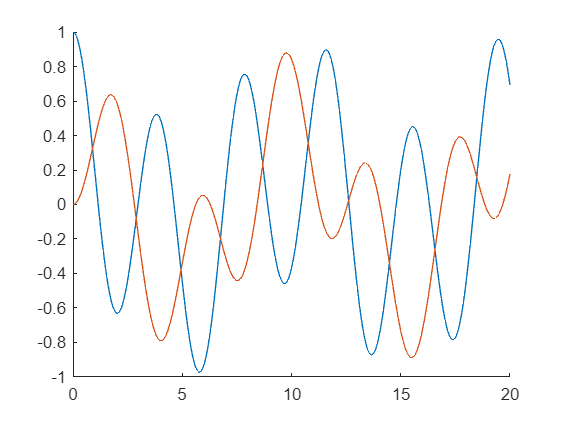

fplot(@(x)deval(sol,x,2), [0, 20])
fplot(@(x)deval(sol,x,3), [0, 20])